# Time series models

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of time series models, and indeed how these can be handled in MATLAB. This file begins with some elementary illustrations of 1st order time series models and how the parameters can be determined directly from data.

In the long term, time series models will be treated using Z-transforms which MATLAB handles formally using tools in the control toolbox.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Savings models

- More generic 1st order time series model

- Modelling from data

- Higher order models

## 1. Technical and mathematical background

It is often convenient to consider values at distinct points in time rather than as continuous signals.

- Rainfall charts may be weekly, monthly or yearly.

- Car sales similarly are usually by month or year.

Within engineering, such scenarios are equally common when measurements can only be taken at specific points in time.

- A chemical process needs a laboratory test to compute quality.

- Objects can only be viewed at certain times (e.g. stars, planets, the moon, rotating objects).

- Anything where the measurement is collected by a computer and which automatically runs on a digital clock.

## 2. Savings models

Savings models are an easy example many can relate to. George deposits *S(0) *=£1000 in a savings account which pays an interest rate of *p*=10% a year, paid annually. The savings model for the amount *S(n)* after n years takes the format:


$$\begin{array}{l}
S\left(1\right)=\left(1+p\right)S\left(0\right)\\
S\left(2\right)=\left(1+p\right)S\left(1\right)={\left(1+p\right)}^2 S\left(0\right)\\
S\left(3\right)=\left(1+p\right)S\left(2\right)={\left(1+p\right)}^3 S\left(0\right)
\end{array}$$


A more generic model could be written as:

$S\left(n\right)=\beta S\left(n-1\right)$  where here $\beta =1+p$

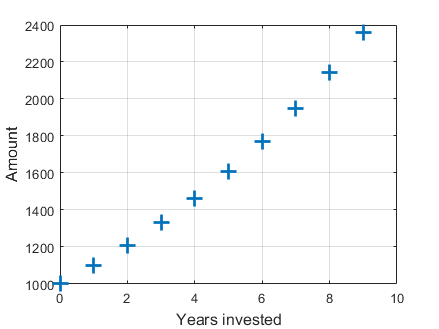

S=1000;p=0.1;
k=1:10;
R=(1+p).^(k-1);
S(k)=S*R;
C=30;
figure; clf 
plot(k-1,S,'+','markersize',12,'linewidth',2); 
grid
xlabel('Years invested','fontsize',12)
ylabel('Amount','fontsize',12)

## 3. More generic 1st order time series model

Often banks make annual charges, so you get the interest minus the charge. An appropriate model for this would be:


$$S\left(n\right)=\beta S\left(n-1\right)-\gamma$$


In terms of coding, this may be more easily handled using a loop. Here assume an annual charge of £30.

disp('Savings with charges section')

Savings with charges section


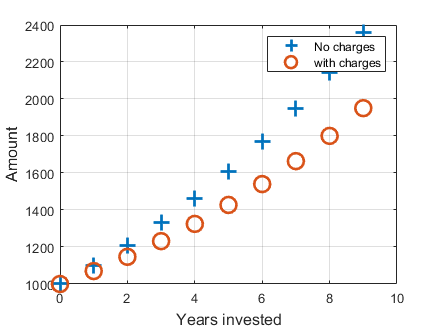

S=1000;p=0.1;SS=S;C=30;
k=1:10;
for kk=2:10
    SS(kk)=SS(kk-1)*(1+p)-C;
    S(kk)=S(kk-1)*(1+p);
end
figure; clf 
plot(k-1,S,'+','markersize',12,'linewidth',2); hold on
plot(k-1,SS,'o','markersize',12,'linewidth',2); hold on
legend('No charges','with charges')
grid
xlabel('Years invested','fontsize',12)
ylabel('Amount','fontsize',12)

## 4. Modelling from data

In many cases we have engineering data which we believe has a simple time series model. Our objective is to determine those model parameters from the data. Such a topic is well beyond an introductory course and would more formally come under the topic of identification (for which there is a MATLAB toolbox). Here we illustrate with some code snippets that in the case of 1st order models, simple code will often suffice.

Taking logarithms of the model $S\left(n\right)=\beta^n S\left(0\right)\;$gives:


$$\log \left(S\left(n\right)\right)\;=\;\textrm{nlog}\left(\beta \right)+\log \left(S\left(0\right)\right)$$


So the adapted model with a scale expressed in samples 'n' has a slope of $\log \left(\beta \right)$ which can be determined from a straightline fit as seen in the figure here. To make the scenario more authentic for real engineering scenarios, some random variation has been added to the core data.

disp('Modelling from data section')

Modelling from data section


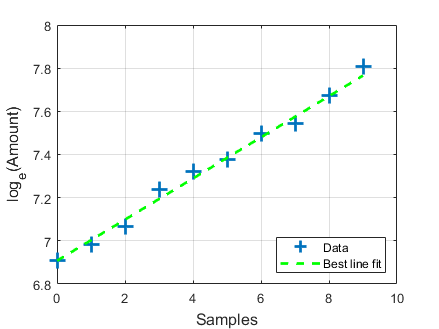

figure; clf 
S=1000;p=0.1;k=1:10;R=(1+p).^(k-1);S(k)=S*R;
n=[0,-20,-40,60,50,-10,30,-60,10,100];
plot(k-1,log(S+n),'+','markersize',12,'linewidth',2); hold on
plot(k-1,log(S),'g--','linewidth',2)
grid
legend('Data','Best line fit','Location','southeast')
xlabel('Samples','fontsize',12)
ylabel('log_e(Amount)','fontsize',12)

**Temperature fitting example**

This example has much larger numbers of data points and shows the use of ***polyfit*** to find the best straightline fit.

disp('Temperature fitting example')

Temperature fitting example


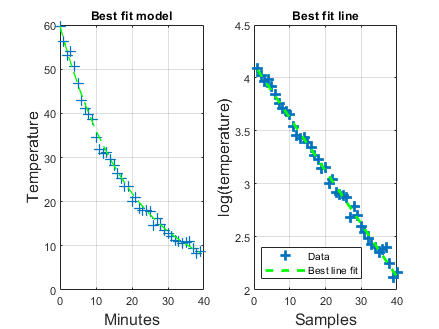

T=[60];
T=T*0.95.^(0:39) + randn(1,40);
k=1:length(T);

% Find best fit model
logT=log(T);
p=polyfit(k,logT,1);
pT=polyval(p,k);
a=exp(p(1));

% underlying model response
A=a.^(k-1);
AT=A*T(1);

figure; clf
subplot(121)
plot(k-1,T,'+','markersize',8,'linewidth',1); hold on
plot(k-1,AT,'g--','linewidth',1)
grid
xlabel('Minutes','fontsize',12)
ylabel('Temperature','fontsize',12)
title('Best fit model')
subplot(122)
plot(k,logT,'+','markersize',8,'linewidth',2); hold on
plot(k,pT,'g--','linewidth',2);
xlabel('Samples','fontsize',12)
ylabel('log(temperature)','fontsize',12)
title('Best fit line')
legend('Data','Best line fit','Location','southwest')
grid

## 5. Higher order models

Higher order time series models take the following form


$$y\left(k\right)+a\left(1\right)y\left(k-1\right)+a\left(2\right)y\left(k-2\right)+\cdots =b\left(1\right)u\left(k\right)+b\left(2\right)u\left(k-1\right)+\cdots$$


The handling of these is easiest with more formal control toolbox tools, to be discussed in other files and also goes beyond the remit of a simple introduction.